cr=0.5;
A=double(rgb2gray(imread('pic.jpg')))/255;
figure();
subplot(221);imshow(A);title('原图像');

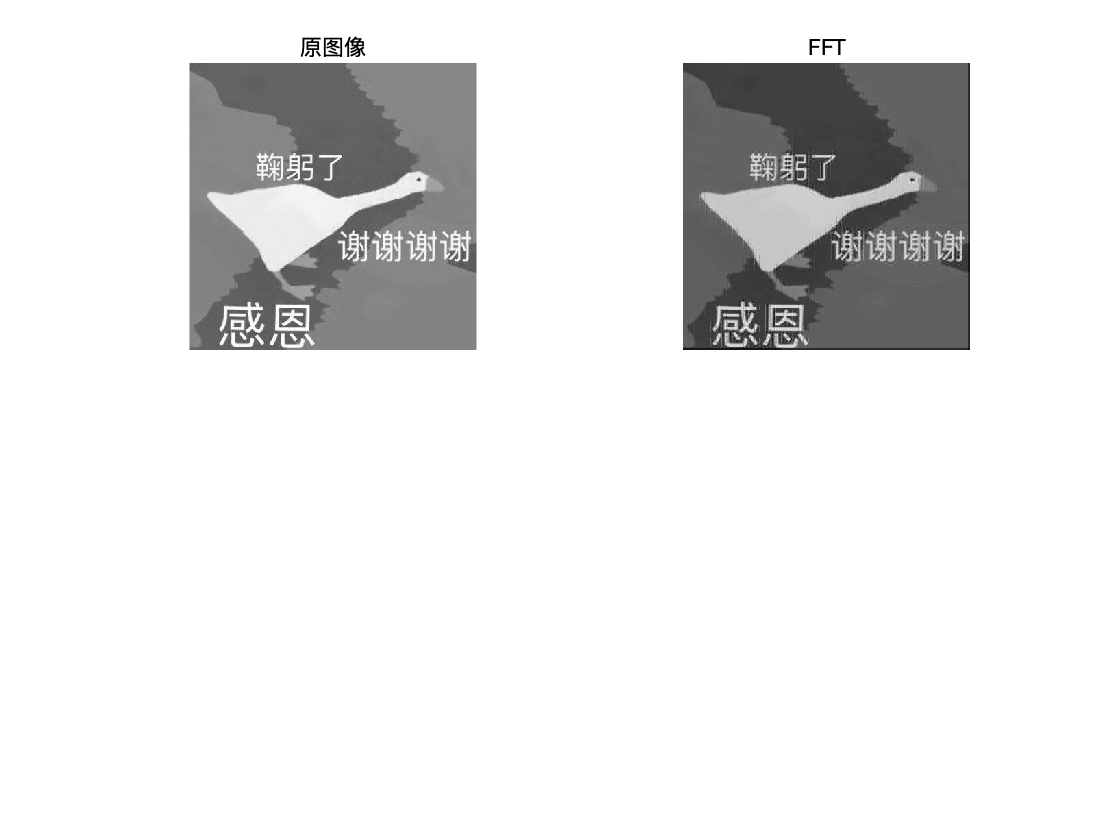

fftcoe=blkproc(A,[8,8],'fft2(x)');
coevar=im2col(fftcoe,[8,8],'distinct');
coe=coevar;
[y,ind]=sort(coevar);
[m,n]=size(coevar);
snum=64-64*cr;
for i = 1: n
    coe(ind(1: snum), i) = 0;
end
B = col2im(coe, [8,8], [419,419], 'distinct');
C = blkproc(B, [8,8], 'ifft2(x)');
subplot(222);imshow(C, [ ]);title('FFT');

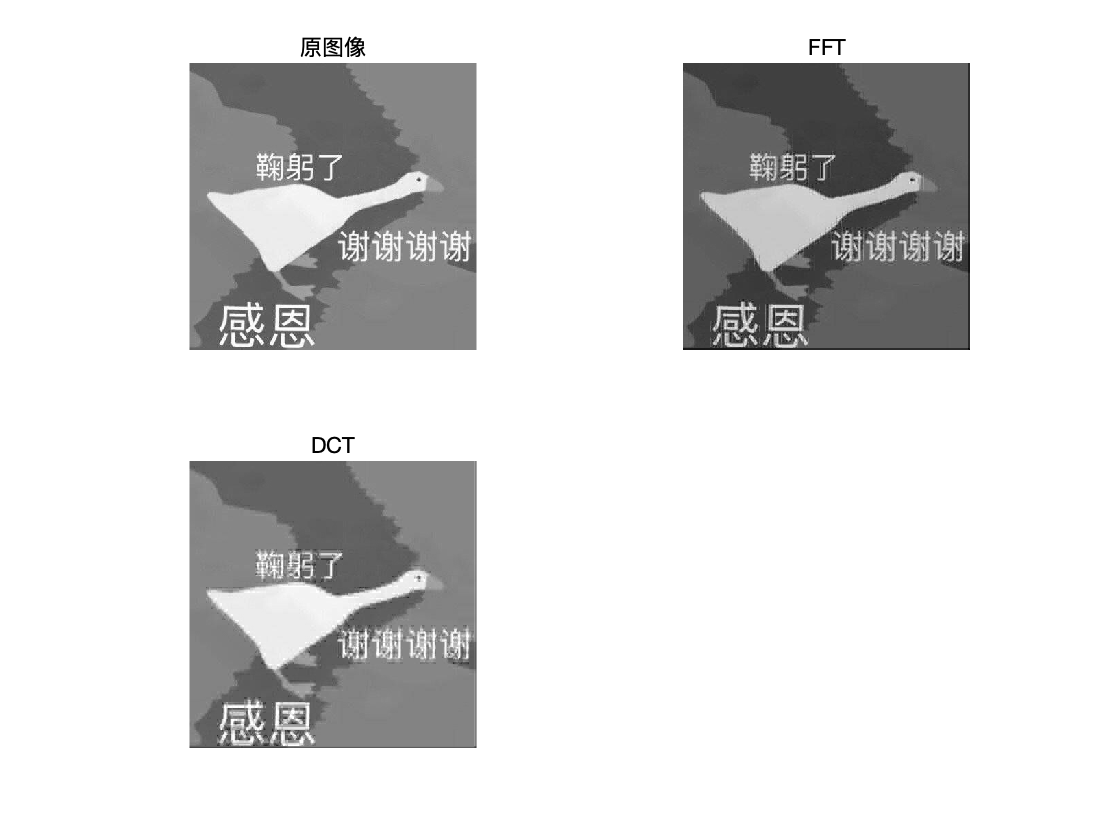

t = dctmtx(8);
dctcoe = blkproc(A, [8 8], 'P1*x*P2', t, t');
coevar = im2col(dctcoe, [8 8], 'distinct');
coe = coevar;
[y, ind] = sort(coevar);
[m, n] = size(coevar);
snum = 64-64 * cr;
for i = 1:n
    coe(ind(1:snum), i) = 0;
end
b2 = col2im(coe, [8 8], [419,419], 'distinct');
i2 = blkproc(b2, [8 8], 'P1*x*P2', t', t);
subplot(223);
imshow(i2);title('DCT');